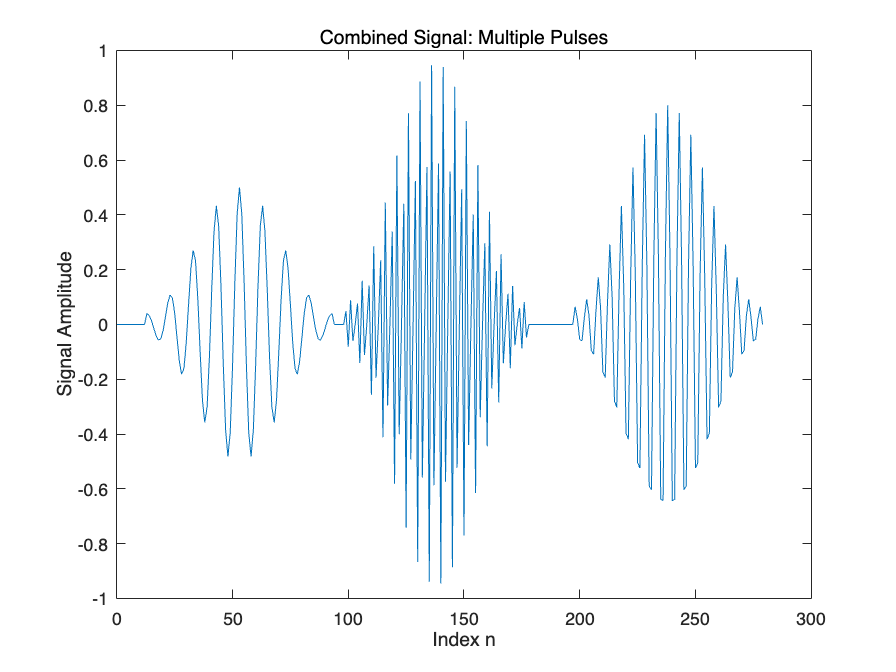

%% DSP Week 12 Assignment 

% Pulse Parameters
width = 81;
omega_vals = pi * [0.2 0.8 0.4];
start_points = [14 99 199];

% Signal Construction
sig = zeros(1, max(start_points) + width);
win = hamming(width)';

% Pulse 1
part = 0.5 * win .* cos((0:width-1) * omega_vals(1));
range = start_points(1):start_points(1)+width-1;
sig(range) = sig(range) + part;

% Pulse 2
part = 1.0 * win .* sin((0:width-1) * omega_vals(2));
range = start_points(2):start_points(2)+width-1;
sig(range) = sig(range) + part;

% Pulse 3
part = 0.8 * win .* cos((0:width-1) * omega_vals(3));
range = start_points(3):start_points(3)+width-1;
sig(range) = sig(range) + part;

% Plot original signal
figure;
plot(0:length(sig)-1, sig);
xlabel('Index n');
ylabel('Signal Amplitude');
title('Combined Signal: Multiple Pulses');

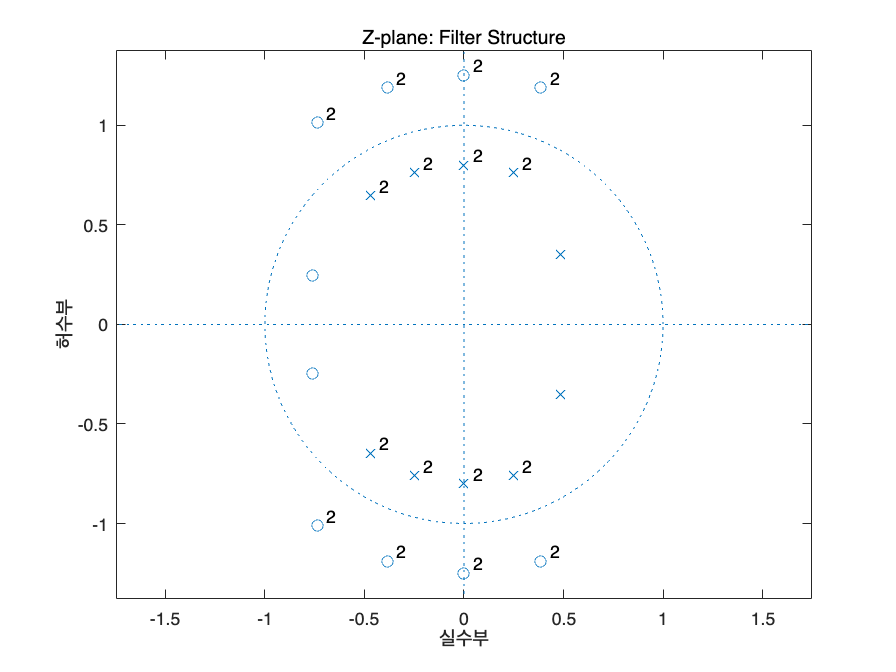


%% Filter Design - Blocking first pulse
num1 = poly([0.8*exp(1i*0.9*pi), 0.8*exp(-1i*0.9*pi)]);
den1 = poly([0.6*exp(1i*0.2*pi), 0.6*exp(-1i*0.2*pi)]);

% All-pass delay filter (for second pulse)
num2 = 1; den2 = 1;
for i = 1:4
    pole = 0.8 * exp(1i*(0.3*pi + 0.1*pi*i));
    zeros_temp = poly([1/conj(pole), 1/pole, 1/conj(pole), 1/pole]);
    poles_temp = poly([pole, conj(pole), pole, conj(pole)]);
    num2 = conv(num2, zeros_temp);
    den2 = conv(den2, poles_temp);
end

% Combine filters
final_num = conv(num1, num2);
final_den = conv(den1, den2);

% Plot Z-plane
figure;
zplane(final_num, final_den);
title('Z-plane: Filter Structure');

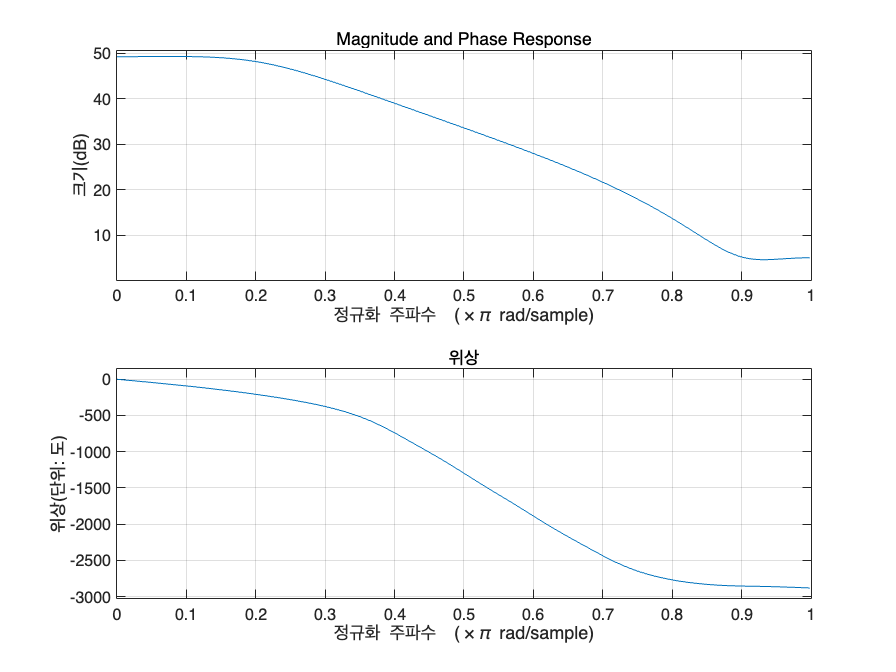


% Frequency response
figure;
freqz(final_num, final_den);
title('Magnitude and Phase Response');

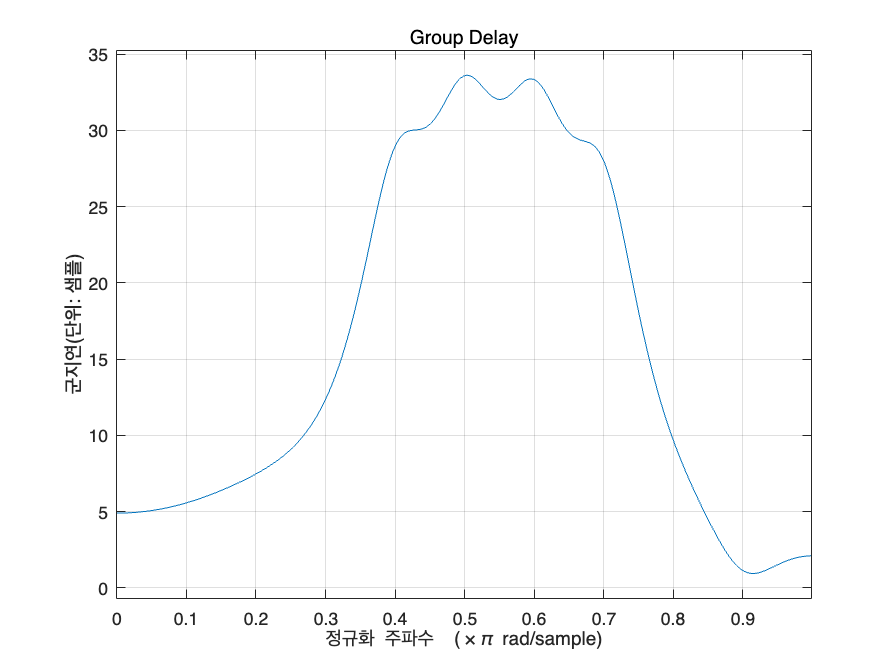


% Group delay
figure;
grpdelay(final_num, final_den);
title('Group Delay');

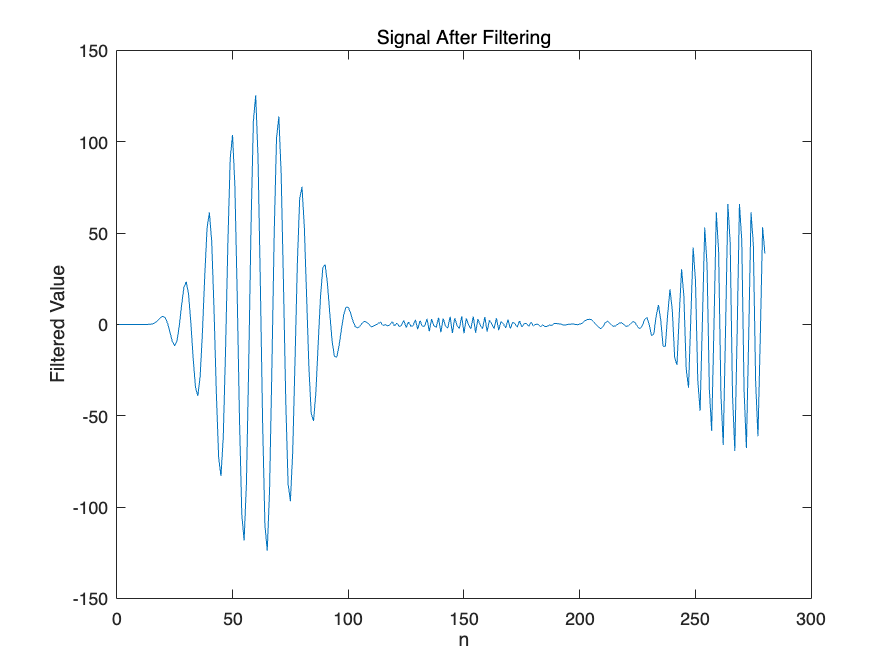


% Apply filter to signal
filtered_sig = filter(final_num, final_den, sig);
figure;
plot(filtered_sig);
xlabel('n');
ylabel('Filtered Value');
title('Signal After Filtering');

# **Problem2**

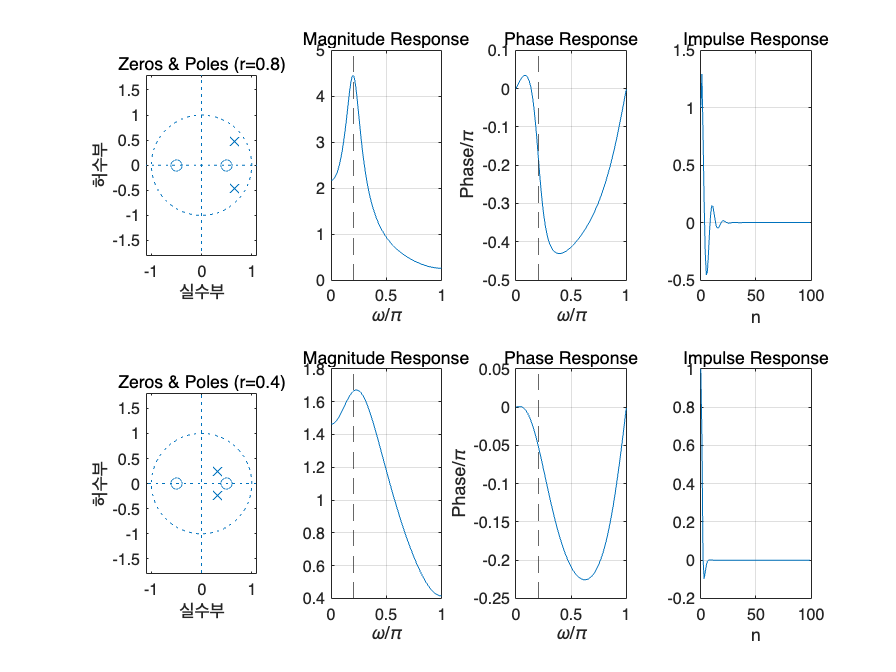

%% DSP Homework Week 12 - Task 2 (Modified Variables and Comments)

%% Define base parameters
ang = pi/5;
b_coeff = conv([1 0.5], [1 -0.5]);  % Numerator polynomial: product of (1 + 0.5z^-1)(1 - 0.5z^-1)

% Case A: pole radius = 0.8
rA = 0.8;
a_coeff_A = poly([rA*exp(1i*ang), rA*exp(-1i*ang)]);  % Denominator for r = 0.8
[respA, freqA] = freqz(b_coeff, a_coeff_A, 1024);
[impA, idxA] = impz(b_coeff, a_coeff_A, 100);

% Case B: pole radius = 0.4
rB = 0.4;
a_coeff_B = poly([rB*exp(1i*ang), rB*exp(-1i*ang)]);
[respB, freqB] = freqz(b_coeff, a_coeff_B, 1024);
[impB, idxB] = impz(b_coeff, a_coeff_B, 100);

% Plotting frequency and impulse response
figure(6)
subplot(2,4,1); zplane(b_coeff, a_coeff_A); title('Zeros & Poles (r=0.8)');
subplot(2,4,2); plot(freqA/pi, abs(respA)); xline(ang/pi, '--'); title('Magnitude Response'); xlabel('\omega/\pi'); grid on;
subplot(2,4,3); plot(freqA/pi, unwrap(angle(respA))/pi); xline(ang/pi, '--'); title('Phase Response'); xlabel('\omega/\pi'); ylabel('Phase/\pi'); grid on;
subplot(2,4,4); plot(idxA, impA); title('Impulse Response'); xlabel('n'); grid on;

subplot(2,4,5); zplane(b_coeff, a_coeff_B); title('Zeros & Poles (r=0.4)');
subplot(2,4,6); plot(freqB/pi, abs(respB)); xline(ang/pi, '--'); title('Magnitude Response'); xlabel('\omega/\pi'); grid on;
subplot(2,4,7); plot(freqB/pi, unwrap(angle(respB))/pi); xline(ang/pi, '--'); title('Phase Response'); xlabel('\omega/\pi'); ylabel('Phase/\pi'); grid on;
subplot(2,4,8); plot(idxB, impB); title('Impulse Response'); xlabel('n'); grid on;

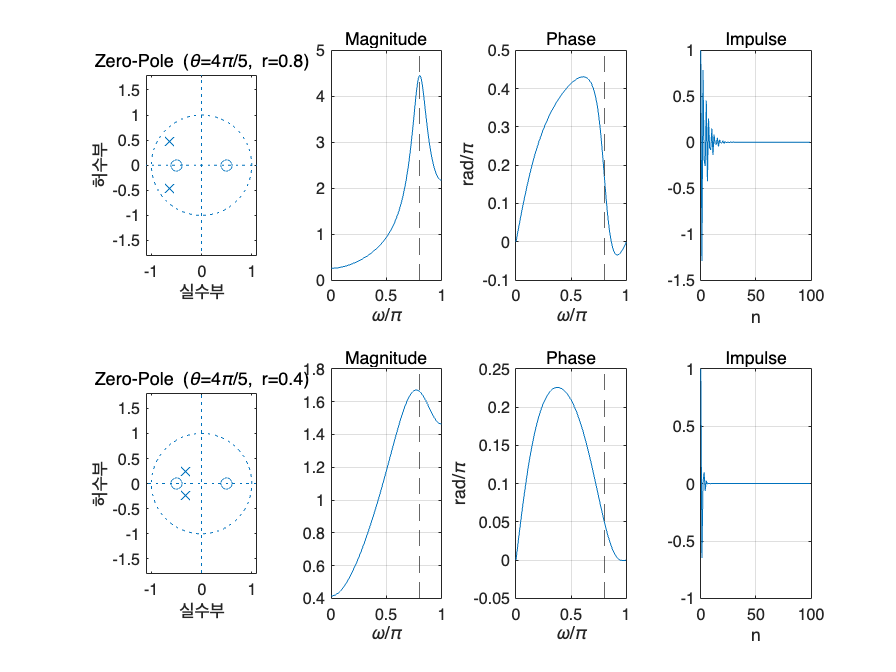


%% Test with different angle
alt_ang = 4*pi/5;
b_alt = b_coeff;

% Case High: r = 0.8
r_hi = 0.8;
a_hi = poly([r_hi*exp(1i*alt_ang), r_hi*exp(-1i*alt_ang)]);
[resp_hi, freq_hi] = freqz(b_alt, a_hi, 1024);
[imp_hi, idx_hi] = impz(b_alt, a_hi, 100);

% Case Low: r = 0.4
r_lo = 0.4;
a_lo = poly([r_lo*exp(1i*alt_ang), r_lo*exp(-1i*alt_ang)]);
[resp_lo, freq_lo] = freqz(b_alt, a_lo, 1024);
[imp_lo, idx_lo] = impz(b_alt, a_lo, 100);

% Plot results for alternative angle
figure(7)
subplot(2,4,1); zplane(b_alt, a_hi); title('Zero-Pole (\theta=4\pi/5, r=0.8)');
subplot(2,4,2); plot(freq_hi/pi, abs(resp_hi)); xline(alt_ang/pi, '--'); title('Magnitude'); xlabel('\omega/\pi'); grid on;
subplot(2,4,3); plot(freq_hi/pi, unwrap(angle(resp_hi))/pi); xline(alt_ang/pi, '--'); title('Phase'); xlabel('\omega/\pi'); ylabel('rad/\pi'); grid on;
subplot(2,4,4); plot(idx_hi, imp_hi); title('Impulse'); xlabel('n'); grid on;

subplot(2,4,5); zplane(b_alt, a_lo); title('Zero-Pole (\theta=4\pi/5, r=0.4)');
subplot(2,4,6); plot(freq_lo/pi, abs(resp_lo)); xline(alt_ang/pi, '--'); title('Magnitude'); xlabel('\omega/\pi'); grid on;
subplot(2,4,7); plot(freq_lo/pi, unwrap(angle(resp_lo))/pi); xline(alt_ang/pi, '--'); title('Phase'); xlabel('\omega/\pi'); ylabel('rad/\pi'); grid on;
subplot(2,4,8); plot(idx_lo, imp_lo); title('Impulse'); xlabel('n'); grid on;

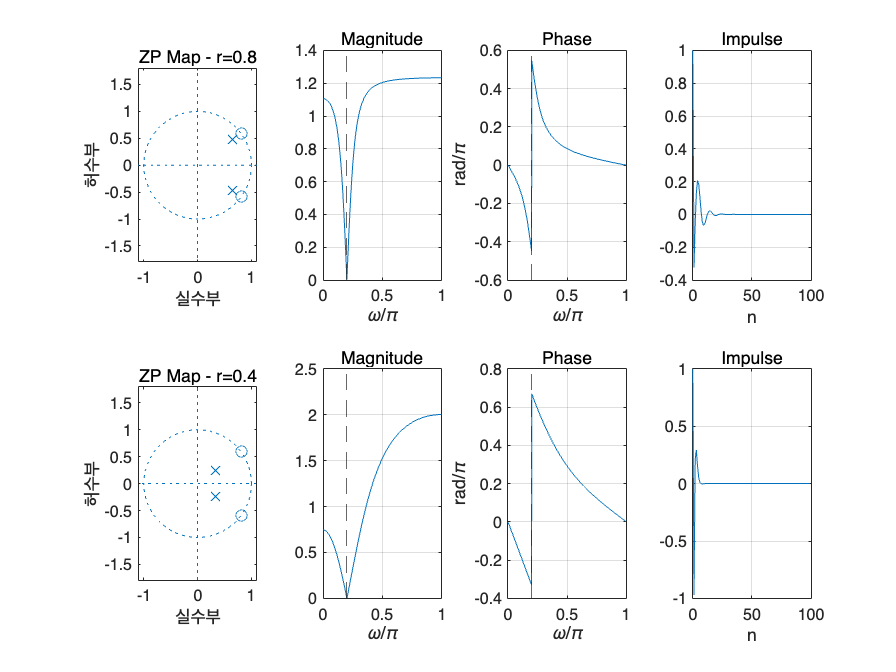


%% Final case with custom numerator
final_theta = pi/5;
b_new = poly([exp(1i*final_theta), exp(-1i*final_theta)]);

rA2 = 0.8;
aA2 = poly([rA2*exp(1i*final_theta), rA2*exp(-1i*final_theta)]);
[resA2, wA2] = freqz(b_new, aA2, 1024);
[impA2, nA2] = impz(b_new, aA2, 100);

rB2 = 0.4;
aB2 = poly([rB2*exp(1i*final_theta), rB2*exp(-1i*final_theta)]);
[resB2, wB2] = freqz(b_new, aB2, 1024);
[impB2, nB2] = impz(b_new, aB2, 100);

figure(8)
subplot(2,4,1); zplane(b_new, aA2); title('ZP Map - r=0.8');
subplot(2,4,2); plot(wA2/pi, abs(resA2)); xline(final_theta/pi, '--'); title('Magnitude'); xlabel('\omega/\pi'); grid on;
subplot(2,4,3); plot(wA2/pi, unwrap(angle(resA2))/pi); xline(final_theta/pi, '--'); title('Phase'); xlabel('\omega/\pi'); ylabel('rad/\pi'); grid on;
subplot(2,4,4); plot(nA2, impA2); title('Impulse'); xlabel('n'); grid on;

subplot(2,4,5); zplane(b_new, aB2); title('ZP Map - r=0.4');
subplot(2,4,6); plot(wB2/pi, abs(resB2)); xline(final_theta/pi, '--'); title('Magnitude'); xlabel('\omega/\pi'); grid on;
subplot(2,4,7); plot(wB2/pi, unwrap(angle(resB2))/pi); xline(final_theta/pi, '--'); title('Phase'); xlabel('\omega/\pi'); ylabel('rad/\pi'); grid on;
subplot(2,4,8); plot(nB2, impB2); title('Impulse'); xlabel('n'); grid on;